# MaxVogelCurveFitting

Author: Max Vogel

Create some independent variable values dependent variable values with nonlinear dependence and one parameter (omega).

t=[0:.1:4*pi]';
n=length(t);
omega=1;
A=2;
y=A*sin(omega*t);

Add random values to dependent variable values using [randn](https://www.mathworks.com/help/matlab/ref/randn.html). The random values are normally distributed with 0 mean and unit variance  Be careful to create a column vector.

y = y + randn(n,1);

Make column vector `yerr` of uniform unit estimated errors using [ones](https://www.mathworks.com/help/matlab/ref/ones.html).

yerr = ones(1,n);

Plot `y` versus `t` with errors `yerr` using [errorbar](https://www.mathworks.com/help/matlab/ref/errorbar.html).

errorbar(t,y, yerr,'-')
xlabel('Time (s)')
ylabel('Vertical position (m)')

Create model function

modelfun= @(b,t)(b(1)*sin(b(2)*t))

modelfun = function_handle with value:
    @(b,t)(b(1)*sin(b(2)*t))


Initialize parameter estimates.

b0=[1,1];

Set options

opts = statset('nlinfit');

Call [nlinfit](https://www.mathworks.com/help/releases/R2020a/stats/nlinfit.html?browser=F1help).

[beta,R,J,CovB,MSE,ErrorModelInfo] = ...
    nlinfit(t,y,modelfun,b0);

List results for parameters.

beta

beta =     2.0662    0.9977


R

R =    -2.2584
    2.2233
    0.3254
    0.9819
   -1.6882
   -0.6196
   -0.3130
    0.3827
   -1.7150
    0.4225


J

J =          0         0
    0.0996    0.2056
    0.1982    0.4050
    0.2948    0.5923
    0.3886    0.7615
    0.4784    0.9072
    0.5635    1.0242
    0.6430    1.1077
    0.7160    1.1538
    0.7820    1.1590


CovB

CovB =     0.0169    0.0001
    0.0001    0.0001


MSE

MSE = 1.0571

ErrorModelInfo

ErrorModelInfo = struct with fields:
              ErrorModel: 'constant'
         ErrorParameters: 1.0281
           ErrorVariance: @(x)mse*ones(size(x,1),1)
                     MSE: 1.0571
          ScheffeSimPred: 3
          WeightFunction: 0
            FixedWeights: 0
    RobustWeightFunction: 0


Compute standard errors on parameters

sqrt(diag(CovB))

ans =     0.1299
    0.0087


Superpose fit on plot with labels and legend.

hold on
yfit=modelfun(beta,t);
plot(t,yfit)

Label, entitle, and legend the plot.

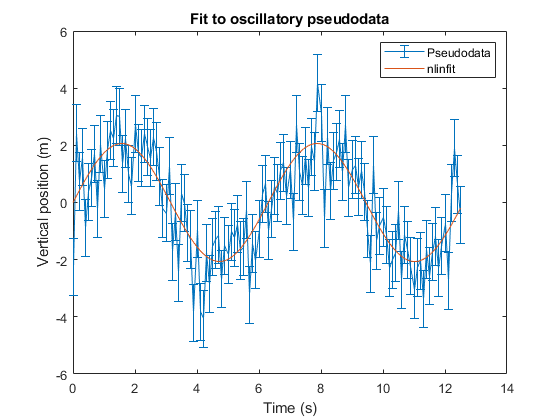

legend('Pseudodata','nlinfit')
title('Fit to oscillatory pseudodata')
hold off